%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SEP: A Stable Election Protocol for clustered                        %
%      heterogeneous wireless sensor networks                          %
% (c) Georgios Smaragdakis                                             %
% WING group, Computer Science Department, Boston University           %
% You can find full documentation and related information at:          %
% http://csr.bu.edu/sep                                                %
% To report your comment or any bug please send e-mail to:             %
% gsmaragd@cs.bu.edu                                                   %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This is the LEACH [1] code we have used.                             %
% The same code can be used for FAIR if m=1                            %
% [1] W.R.Heinzelman, A.P.Chandrakasan and H.Balakrishnan,             %
%     "An application-specific protocol architecture for wireless      % 
%      microsensor networks"                                           % 
%     IEEE Transactions on Wireless Communications, 1(4):660-670,2002  %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all; clc,
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Field Dimensions - x and y maximum (in meters)
xm = 1000;
ym = 1000;
%Creating obstacles
mountain = [1, 1; 1, 100; 100, 100; 100, 1;1,1];
forest = [800, 500; 800, 900; 900, 900; 900, 500;800,500];

%x and y Coordinates of the Sink
sink.x=xm/2;
sink.y=ym;
%Number of Nodes in the field
n = 100;
%Optimal Election Probability of a node to become cluster head
p=0.10;
packetLength =6400;
ctrPacketLength = 200;
%Energy Model (all values in Joules)
%Initial Energy 
Eo = 0.01;
tx_power=30;
min_power=-80;
%Eelec=Etx=Erx
ETX=50*0.000000001;
ERX=50*0.000000001;
%Transmit Amplifier types
Efs=10*0.000000000001;
Emp=0.0013*0.000000000001;
%Data Aggregation Energy
EDA=5*0.000000001;
INFINITY = 9999999999999999999999;
%maximum number of rounds
rmax=9999;
%%%%%%%%%%%%%%%%%%%%%%%%% END OF PARAMETERS %%%%%%%%%%%%%%%%%%%%%%%%
%Computation of do
do=sqrt(Efs/Emp);
%Creation of the random Sensor Network
figure(1);
for i=1:1:n
    S(i).xd=rand(1,1)*xm;  %S=sensor number i
    XR(i)=S(i).xd;
    S(i).yd=rand(1,1)*ym;
    YR(i)=S(i).yd;
    S(i).G=0;
    %initially there are no cluster heads only nodes
    S(i).type='N';
    S(i).E=Eo;
    S(i).ENERGY=0;
    S(i).packToSend=1; %number of data to send, useful for retransmission for CH
    hold on;
    plot(xm,ym,S(i).xd,S(i).yd,'ob',sink.x,sink.y,'*r');
    plot(mountain(:, 1), mountain(:, 2), 'r-', 'LineWidth', 2);
    plot(forest(:, 1), forest(:, 2), 'g-', 'LineWidth', 2);

end
S(n+1).xd=sink.x;
S(n+1).yd=sink.y;

%First Iteration
figure(1);
%counter for CHs
countCHs=0;
%counter for CHs per round
rcountCHs=0;
cluster=1;
countCHs;
rcountCHs=rcountCHs+countCHs;
flag_first_dead=0; 
received=0;
for r=0:1:rmax 
%Operation for epoch
    if(mod(r, round(1/p))==0) 
        for i=1:1:n
            S(i).G=0;
            S(i).cl=0;
        end
    end
    %Number of dead nodes
    dead=0;
    %counter for bit transmitted to Bases Station and to Cluster Heads
    packets_TO_BS=0;
    packets_TO_CH=0;
    %counter for bit transmitted to Bases Station and to Cluster Heads per round
    PACKETS_TO_CH(r+1)=0;
    PACKETS_TO_BS(r+1)=0;
    figure(1);
    for i=1:1:n
        %checking if there is a dead node
        if (S(i).E<=0)
            dead=dead+1;
        end
        if (S(i).E>0)
            S(i).type='N';
        end
    end
    if (dead == n)
        break;
    end
    STATISTICS(r+1).DEAD=dead;
    DEAD(r+1)=dead;
    %When the first node dies
    if (dead==1)
        if(flag_first_dead==0)
            disp(["first_dead=", r])
            flag_first_dead=1;
        end
    end
    countCHs=0;
    cluster=1;
    for i=1:1:n
        if(S(i).E>0)
            temp_rand=rand;     
            if ((S(i).G)<=0)
            %Election of Cluster Heads
                if(temp_rand <=(p/(1-p*mod(r,round(1/p)))))
                    countCHs = countCHs+1;
                    
                    S(i).type = 'C';
                    S(i).G = round(1/p)-1;
                    C(cluster).xd = S(i).xd;
                    C(cluster).yd = S(i).yd;
                    distance=sqrt((S(i).xd-(S(n+1).xd))^2 + (S(i).yd-(S(n+1).yd))^2);
                    C(cluster).distance = distance;
                    C(cluster).id = i;
                    X(cluster)=S(i).xd;
                    Y(cluster)=S(i).yd;
                    cluster=cluster+1;
                    distanceBroad = sqrt(xm*xm+ym*ym);      
                end     
            end
        end 
    end
    STATISTICS(r+1).CLUSTERHEADS = cluster-1;
    CLUSTERHS(r+1)= cluster-1;

    %Election of Associated Cluster Head for Normal Nodes
    for i=1:1:n
        if (S(i).type=='N' && S(i).E>0)
            min_dis = INFINITY; 
            if(cluster-1>=1)
                min_dis_cluster = 1;
                for c = 1:1:cluster-1 
                    temp = sqrt((S(i).xd - X(c))^2 + (S(i).yd - Y(c))^2);
                    if (temp<min_dis)
                        min_dis = temp;
                        min_dis_cluster = c;
                        %c est le cluster auquel il appartient, C(c) est le Cluster
                        %head
                    end
                end
                S(i).min_dis = min_dis;
                S(i).min_dis_cluster = min_dis_cluster;
            end
            elseif (S(i).type=='N' && S(i).E<=0)
            S(i).min_dis_cluster=1;
        end
    end

    %hold on;
    countCHs;
    rcountCHs = rcountCHs + countCHs;
    %plotting the network
    if r==12
        for j=1:1:n
            if (S(j).type=='C' && S(j).E>0)
                plot([S(j).xd S(n+1).xd], [S(j).yd S(n+1).yd])
                hold on
            elseif (S(j).E>0)
                plot([S(j).xd X(S(j).min_dis_cluster)], [S(j).yd Y(S(j).min_dis_cluster)])
                hold on
            end
        end
    end
    %Sending messages
    %first the Nodes send
    for j=1:1:n
        if (S(j).E>0 && S(j).type=='N')
            min_dis=S(j).min_dis;
            %cost of sending control and data packet
            S(j).E = S(j).E -(ETX*(ctrPacketLength) + Efs*ctrPacketLength); 
            S(j).E = S(j).E -(ETX*(packetLength) + Efs*packetLength);
            
            %cost of receiving the packet for the CH
            %is the packet received ?
            power=tx_power;
            %is the paquet going through hard terrain?
            source=[S(j).xd,S(j).yd];
            dest=[S(C(S(j).min_dis_cluster).id).xd,S(C(S(j).min_dis_cluster).id).yd];
            distTemp=pdist2(source,dest);
            [in1,dist1]=distInRegion(source,dest,mountain);
            [in2,dist2]=distInRegion(source,dest,forest);

            %is the packet received? 
            power=calcLossEnv(in1,dist1,2.5,power);
            distTemp=distTemp-dist1;

            power=calcLossEnv(in2,dist2,2,power);
            distTemp=distTemp-dist2;

            power_lost=SendSignal(1,distTemp);
            power=power-power_lost;
            if((power)>min_power)
                S(C(S(j).min_dis_cluster).id).packToSend=S(C(S(j).min_dis_cluster).id).packToSend+1;
                if(min_dis > 0)
                    S(C(min_dis_cluster).id).E = S(C(min_dis_cluster).id).E - ((ERX + EDA)*packetLength );
                    S(C(min_dis_cluster).id).E = S(C(min_dis_cluster).id).E - ERX *ctrPacketLength ; 
                end
            end
        end
    end

    %then the CH send
    for j=1:1:n
        if (S(j).E>0 && S(j).type=='C')
        %sending its control packet 
            S(j).E = S(j).E-(ETX*ctrPacketLength + Efs*ctrPacketLength);             
            %sending the data packets
            while (S(j).packToSend>0 && S(j).E>0)
                distance=sqrt((S(j).xd-(S(n+1).xd))^2 + (S(j).yd-(S(n+1).yd))^2);
                S(j).E = S(j).E-((ETX+EDA)*packetLength+ Efs*packetLength);
                
                power=tx_power;
                %is the paquet going through hard terrain?
                source=[S(j).xd,S(j).yd];
                dest=[(S(n+1).xd),(S(n+1).yd)];
                distTemp=pdist2(source,dest);
                [in1,dist1]=distInRegion(source,dest,mountain);
                [in2,dist2]=distInRegion(source,dest,forest);
                
                %is the packet received?
                power=calcLossEnv(in1,dist1,2.5,power);
                distTemp=distTemp-dist1;

                power=calcLossEnv(in2,dist2,2,power);
                distTemp=distTemp-dist2;
            
                power_lost=SendSignal(1,distTemp);
                power=power-power_lost;
                S(j).packToSend=S(j).packToSend-1;
                if((power)>min_power)
                    PACKETS_TO_BS(r+1)=PACKETS_TO_BS(r+1)+1;
                    received=received+1;
                end
            end
        end
        S(j).packToSend=1;
    end
end

    "first_dead="    "1"



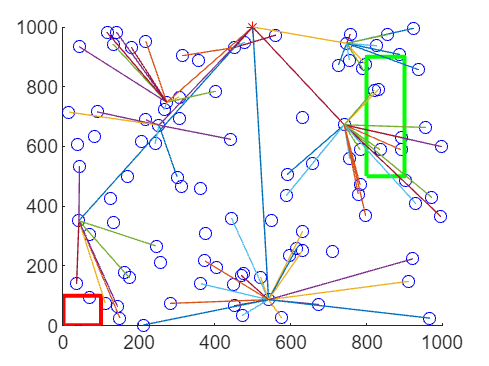

x=1:1:r;
y=1:1:r;

%stats nulber of dead nodes
for i=1:1:r
    x(i)=i;
    y(i) = n - STATISTICS(i).DEAD;
end
hold off;

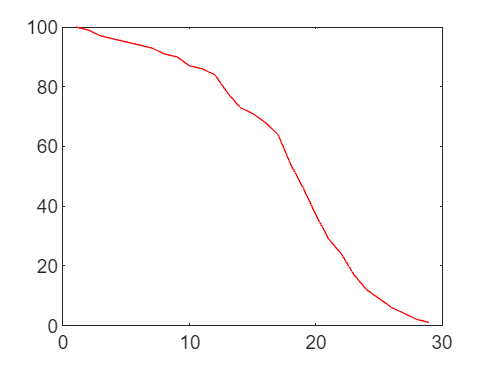

figure(2)
plot(x,y,'r');

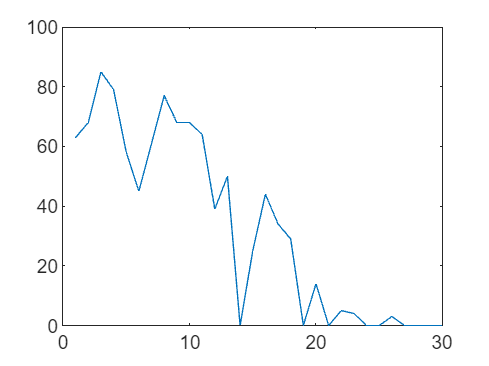

figure(3)
plot(PACKETS_TO_BS)

disp(["number of packets received by BS=",received])

    "number of packets received by BS="    "983"



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   STATISTICS    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                                                     %
%  DEAD  : a rmax x 1 array of number of dead nodes/round 
%  DEAD_A : a rmax x 1 array of number of dead Advanced nodes/round
%  DEAD_N : a rmax x 1 array of number of dead Normal nodes/round
%  CLUSTERHS : a rmax x 1 array of number of Cluster Heads/round
%  PACKETS_TO_BS : a rmax x 1 array of number packets send to Base Station/round
%  PACKETS_TO_CH : a rmax x 1 array of number of packets send to ClusterHeads/round
%  first_dead: the round where the first node died                   
%                                                                                     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%sink(50,175) ,ctrPacketLength=200,packetLength=4000,Eo=2J.